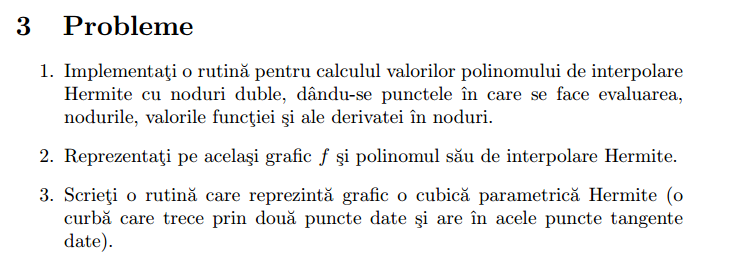

f  = @(x) sin(pi .* x ./ 2) + 1;
x  = linspace(pi/2, 3*pi/2, 2);
y  = f(x);
dy = (pi/2) * cos(pi.*x/2);

num_points = 200;
xx = linspace(min(x), max(x), num_points);

[H, Q] = HermitePowell(x, y, dy, xx);
Q

Q =     1.6243         0         0         0
    1.6243   -1.2271         0         0
    1.8997    0.0877    0.4185         0
    1.8997    0.6858    0.1904   -0.0726


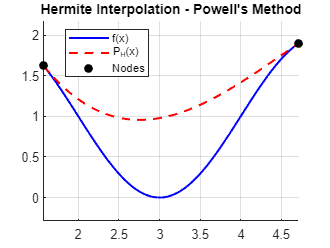


figure; 
hold on; grid on;

plot(xx, f(xx), 'b-', 'LineWidth', 1.5, 'DisplayName', 'f(x)');
plot(xx, H, 'r--', 'LineWidth', 1.5, 'DisplayName', 'P_H(x)');
plot(x, y, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Nodes');

title('Hermite Interpolation - Powell''s Method');
legend('Location', 'best');
axis equal;

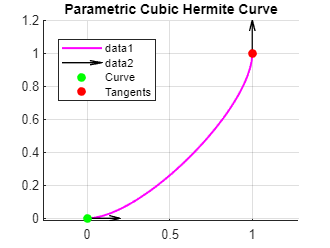

point0 = [0, 0];
point1 = [1, 1];
m0 = [1, 0];
m1 = [0, 1];

t = linspace(0, 1, 100);
[x, y] = CubicHermiteCurve(point0, point1, m0, m1, t);

% Plot curve and its tangents
figure;
hold on; grid on;

plot(x, y, 'm-', 'LineWidth', 1.5); 
quiver([point0(1), point1(1)], [point0(2), point1(2)], [m0(1), m1(1)], [m0(2), m1(2)], 0.2, 'k', 'LineWidth', 1);
plot(point0(1), point0(2), 'go', 'MarkerFaceColor', 'g', 'DisplayName', 'Curve');
plot(point1(1), point1(2), 'ro', 'MarkerFaceColor', 'r', 'DisplayName', 'Tangents');

title('Parametric Cubic Hermite Curve');
legend('Location', 'Best');
axis equal;